# Limpieza de datos

Primero se importan los datos con una función propia (timeTableCratorInador())

refrigerator_1 = timeTableCratorInador(".\Pool1\Sensor1-");
refrigerator_2 = timeTableCratorInador(".\Pool1\Sensor2-");
refrigerator_3 = timeTableCratorInador(".\Pool1\Sensor3-");
refrigerator_4 = timeTableCratorInador(".\Pool1\Sensor5-");
microwave_1 = timeTableCratorInador(".\Pool2\Sensor1-");
microwave_2 = timeTableCratorInador(".\Pool2\Sensor2-");
microwave_3 = timeTableCratorInador(".\Pool2\Sensor3-");

## Crear caso en que dos aparatos esten funcionando al mismo tiempo

Separar en parte real y reactiva y sumarlas.

real = fp*aparente

reactiva = sqrt(aparente^2-real^2)

Modifique la función timeTableCratorInador para que genrara la corriente y potencia real y reactivia

Podemos tener 12 combinaciones diferentes, solo tomare 3 para mantener el valance.

refrigeratorMicrowave_1 = jointApplianceInador(refrigerator_2,microwave_1);
refrigeratorMicrowave_2 = jointApplianceInador(refrigerator_3,microwave_2);
refrigeratorMicrowave_3 = jointApplianceInador(refrigerator_4,microwave_3);

Removere valores reales y reactivos

refrigerator_1 = removevars(refrigerator_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigerator_2 = removevars(refrigerator_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigerator_3 = removevars(refrigerator_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigerator_4 = removevars(refrigerator_4, ["real_power" "reactive_power" "real_current" "reactive_current"]);

microwave_1 = removevars(microwave_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
microwave_2 = removevars(microwave_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
microwave_3 = removevars(microwave_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);

refrigeratorMicrowave_1 = removevars(refrigeratorMicrowave_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigeratorMicrowave_2 = removevars(refrigeratorMicrowave_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigeratorMicrowave_3 = removevars(refrigeratorMicrowave_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);

## Eliminación de datos atípicos

En la fase de limpieza de datos, se llevó a cabo un proceso para eliminar los valores atípicos presentes en los conjuntos de datos de los refrigeradores y microondas. Para lograr esto, se empleó el método de media móvil, una técnica estadística ampliamente utilizada en el análisis de series temporales.

Se estableció un factor de umbral (threshold factor) de 3, que se utilizó como criterio para identificar y descartar los datos considerados como outliers. Este factor permite definir un límite más allá del cual los valores se consideran anómalos en relación con el resto de la distribución de los datos.

Para los refrigeradores, se aplicó una ventana de 5 minutos, lo que significa que se calculó la media móvil utilizando los datos de los 5 minutos anteriores y posteriores a cada punto en el tiempo. Esta ventana temporal se seleccionó para capturar los cambios de consumo de energía más significativos y suavizar las fluctuaciones rápidas que podrían deberse a ruido o eventos transitorios.

En el caso de los microondas, se optó por una ventana de 1 minuto, dado que estos electrodomésticos suelen tener un consumo energético más rápido y con cambios más bruscos en comparación con los refrigeradores.

La eliminación de datos atípicos mediante la media móvil y la aplicación de ventanas de tiempo específicas para cada tipo de dispositivo permitieron obtener conjuntos de datos más limpios y consistentes, preparándolos adecuadamente para las etapas posteriores del análisis y el tratamiento estadístico.

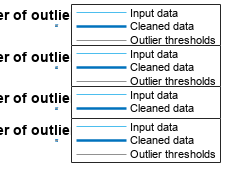

% Fill outliers
[cleanedRefrigerator_1,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(refrigerator_1,"previous","movmedian",minutes(1));

% Display results
f = figure("Units","Normalized");
N = 4;
f.Position = [0 0 1 N/3];
tiledlayout(N,1,"Padding","compact");
for k = 1:N
    nexttile
    plot(refrigerator_1.timeCurrent,refrigerator_1.(k),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(refrigerator_1.timeCurrent,cleanedRefrigerator_1.(k),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Cleaned data")

    % Plot outliers
    plot(refrigerator_1.timeCurrent(outlierIndices(:,k)),refrigerator_1.(k)(outlierIndices(:,k)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(refrigerator_1.timeCurrent(outlierIndices(:,k)),cleanedRefrigerator_1.(k)(outlierIndices(:,k)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([refrigerator_1.timeCurrent(:); missing; refrigerator_1.timeCurrent(:)],...
        [thresholdHigh.(k)(:); missing; thresholdLow.(k)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k)))
    legend("Location","EastOutside")
    ylabel(refrigerator_1.Properties.VariableNames{k},"Interpreter","none")
    if k == N
        xlabel("timeCurrent")
    end
end
f.NextPlot = "new";
clear thresholdLow thresholdHigh f N k

% Fill outliers
[cleanedRefrigerator_2,outlierIndices,thresholdLow2,thresholdHigh2] = ...
    filloutliers(refrigerator_2,"previous","movmedian",minutes(1));

% Display results
f2 = figure("Units","Normalized");
N2 = 4;
f2.Position = [0 0 1 N2/3];
tiledlayout(N2,1,"Padding","compact");
for k2 = 1:N2
    nexttile
    plot(refrigerator_2.timeCurrent,refrigerator_2.(k2),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(refrigerator_2.timeCurrent,cleanedRefrigerator_2.(k2),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Cleaned data")


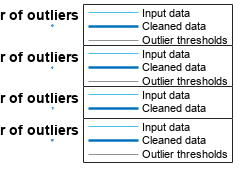

    % Plot outliers
    plot(refrigerator_2.timeCurrent(outlierIndices(:,k2)),refrigerator_2.(k2)(outlierIndices(:,k2)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(refrigerator_2.timeCurrent(outlierIndices(:,k2)),cleanedRefrigerator_2.(k2)(outlierIndices(:,k2)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([refrigerator_2.timeCurrent(:); missing; refrigerator_2.timeCurrent(:)],...
        [thresholdHigh2.(k2)(:); missing; thresholdLow2.(k2)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k2)))
    legend("Location","EastOutside")
    ylabel(refrigerator_2.Properties.VariableNames{k2},"Interpreter","none")
    if k2 == N2
        xlabel("timeCurrent")
    end
end
f2.NextPlot = "new";
clear thresholdLow2 thresholdHigh2 f2 N2 k2


% Fill outliers
[cleanedRefrigerator_3,outlierIndices,thresholdLow3,thresholdHigh3] = ...
    filloutliers(refrigerator_3,"previous","movmedian",minutes(1));

% Display results
f3 = figure("Units","Normalized");
N3 = 4;
f3.Position = [0 0 1 N3/3];
tiledlayout(N3,1,"Padding","compact");
for k3 = 1:N3
    nexttile
    plot(refrigerator_3.timeCurrent,refrigerator_3.(k3),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(refrigerator_3.timeCurrent,cleanedRefrigerator_3.(k3),"Color",[0 114 189]/255,...

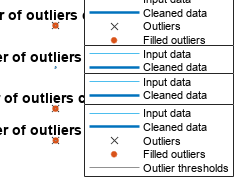

        "LineWidth",1.5,"DisplayName","Cleaned data")

    % Plot outliers
    plot(refrigerator_3.timeCurrent(outlierIndices(:,k3)),refrigerator_3.(k3)(outlierIndices(:,k3)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(refrigerator_3.timeCurrent(outlierIndices(:,k3)),cleanedRefrigerator_3.(k3)(outlierIndices(:,k3)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([refrigerator_3.timeCurrent(:); missing; refrigerator_3.timeCurrent(:)],...
        [thresholdHigh3.(k3)(:); missing; thresholdLow3.(k3)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k3)))
    legend("Location","EastOutside")
    ylabel(refrigerator_3.Properties.VariableNames{k3},"Interpreter","none")
    if k3 == N3
        xlabel("timeCurrent")
    end
end
f3.NextPlot = "new";
clear thresholdLow3 thresholdHigh3 f3 N3 k3


% Fill outliers
[cleanedRefrigerator_4,outlierIndices,thresholdLow4,thresholdHigh4] = ...
    filloutliers(refrigerator_4,"previous","movmedian",minutes(1));

% Display results
f6 = figure("Units","Normalized");
N6 = 4;
f6.Position = [0 0 1 N6/3];
tiledlayout(N6,1,"Padding","compact");
for k6 = 1:N6
    nexttile
    plot(refrigerator_4.timeCurrent,refrigerator_4.(k6),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(refrigerator_4.timeCurrent,cleanedRefrigerator_4.(k6),"Color",[0 114 189]/255,...

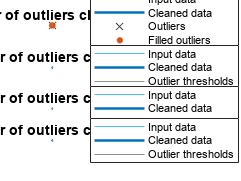

        "LineWidth",1.5,"DisplayName","Cleaned data")

    % Plot outliers
    plot(refrigerator_4.timeCurrent(outlierIndices(:,k6)),refrigerator_4.(k6)(outlierIndices(:,k6)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(refrigerator_4.timeCurrent(outlierIndices(:,k6)),cleanedRefrigerator_4.(k6)(outlierIndices(:,k6)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([refrigerator_4.timeCurrent(:); missing; refrigerator_4.timeCurrent(:)],...
        [thresholdHigh4.(k6)(:); missing; thresholdLow4.(k6)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k6)))
    legend("Location","EastOutside")
    ylabel(refrigerator_4.Properties.VariableNames{k6},"Interpreter","none")
    if k6 == N6
        xlabel("timeCurrent")
    end
end
f6.NextPlot = "new";
clear thresholdLow4 thresholdHigh4 f6 N6 k6


% Fill outliers
[cleanedMicrowave_1,outlierIndices,thresholdLow5,thresholdHigh5] = ...
    filloutliers(microwave_1,"linear","movmedian",minutes(1));

% Display results
f4 = figure("Units","Normalized");
N4 = 4;
f4.Position = [0 0 1 N4/3];
tiledlayout(N4,1,"Padding","compact");
for k4 = 1:N4
    nexttile
    plot(microwave_1.timeCurrent,microwave_1.(k4),"Color",[77 190 238]/255,...
        "DisplayName","Input data")
    hold on
    plot(microwave_1.timeCurrent,cleanedMicrowave_1.(k4),"Color",[0 114 189]/255,...

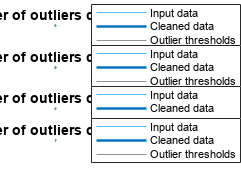

        "LineWidth",1.5,"DisplayName","Cleaned data")

    % Plot outliers
    plot(microwave_1.timeCurrent(outlierIndices(:,k4)),microwave_1.(k4)(outlierIndices(:,k4)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(microwave_1.timeCurrent(outlierIndices(:,k4)),cleanedMicrowave_1.(k4)(outlierIndices(:,k4)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([microwave_1.timeCurrent(:); missing; microwave_1.timeCurrent(:)],...
        [thresholdHigh5.(k4)(:); missing; thresholdLow5.(k4)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k4)))
    legend("Location","EastOutside")
    ylabel(microwave_1.Properties.VariableNames{k4},"Interpreter","none")
    if k4 == N4
        xlabel("timeCurrent")
    end
end
f4.NextPlot = "new";
clear thresholdLow5 thresholdHigh5 f4 N4 k4


% Fill outliers
[cleanedMicrowave_2,outlierIndices,thresholdLow6,thresholdHigh6] = ...
    filloutliers(microwave_2,"linear","movmedian",minutes(1));

% Display results
f28 = figure("Units","Normalized");
N28 = 4;
f28.Position = [0 0 1 N28/3];
tiledlayout(N28,1,"Padding","compact");
for k28 = 1:N28
    nexttile
    plot(microwave_2.timeCurrent,microwave_2.(k28),"Color",[77 190 238]/255,...
        "DisplayName","Input data")
    hold on
    plot(microwave_2.timeCurrent,cleanedMicrowave_2.(k28),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Cleaned data")

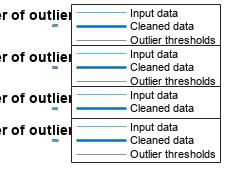


    % Plot outliers
    plot(microwave_2.timeCurrent(outlierIndices(:,k28)),microwave_2.(k28)(outlierIndices(:,k28)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(microwave_2.timeCurrent(outlierIndices(:,k28)),cleanedMicrowave_2.(k28)(outlierIndices(:,k28)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([microwave_2.timeCurrent(:); missing; microwave_2.timeCurrent(:)],...
        [thresholdHigh6.(k28)(:); missing; thresholdLow6.(k28)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k28)))
    legend("Location","EastOutside")
    ylabel(microwave_2.Properties.VariableNames{k28},"Interpreter","none")
    if k28 == N28
        xlabel("timeCurrent")
    end
end
f28.NextPlot = "new";
clear thresholdLow6 thresholdHigh6 f28 N28 k28


% Fill outliers
[cleanedMicrowave_3,outlierIndices,thresholdLow7,thresholdHigh7] = ...
    filloutliers(microwave_3,"previous","movmedian",minutes(1));

% Display results
f14 = figure("Units","Normalized");
N14 = 4;
f14.Position = [0 0 1 N14/3];
tiledlayout(N14,1,"Padding","compact");
for k14 = 1:N14
    nexttile
    plot(microwave_3.timeCurrent,microwave_3.(k14),"Color",[77 190 238]/255,...
        "DisplayName","Input data")
    hold on
    plot(microwave_3.timeCurrent,cleanedMicrowave_3.(k14),"Color",[0 114 189]/255,...

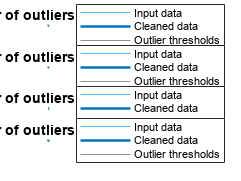

        "LineWidth",1.5,"DisplayName","Cleaned data")

    % Plot outliers
    plot(microwave_3.timeCurrent(outlierIndices(:,k14)),microwave_3.(k14)(outlierIndices(:,k14)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(microwave_3.timeCurrent(outlierIndices(:,k14)),cleanedMicrowave_3.(k14)(outlierIndices(:,k14)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([microwave_3.timeCurrent(:); missing; microwave_3.timeCurrent(:)],...
        [thresholdHigh7.(k14)(:); missing; thresholdLow7.(k14)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k14)))
    legend("Location","EastOutside")
    ylabel(microwave_3.Properties.VariableNames{k14},"Interpreter","none")
    if k14 == N14
        xlabel("timeCurrent")
    end
end
f14.NextPlot = "new";
clear thresholdLow7 thresholdHigh7 f14 N14 k14


% Fill outliers
[cleanedRefrigeratorMicrowave_1,outlierIndices,thresholdLow9,thresholdHigh9] = ...
    filloutliers(refrigeratorMicrowave_1,"previous","movmedian",minutes(1));

% Display results
f29 = figure("Units","Normalized");
N29 = 4;
f29.Position = [0 0 1 N29/3];
tiledlayout(N29,1,"Padding","compact");
for k29 = 1:N29
    nexttile
    plot(refrigeratorMicrowave_1.timeCurrent,refrigeratorMicrowave_1.(k29),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(refrigeratorMicrowave_1.timeCurrent,cleanedRefrigeratorMicrowave_1.(k29),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Cleaned data")


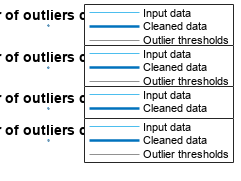

    % Plot outliers
    plot(refrigeratorMicrowave_1.timeCurrent(outlierIndices(:,k29)),refrigeratorMicrowave_1.(k29)(outlierIndices(:,k29)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(refrigeratorMicrowave_1.timeCurrent(outlierIndices(:,k29)),cleanedRefrigeratorMicrowave_1.(k29)(outlierIndices(:,k29)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([refrigeratorMicrowave_1.timeCurrent(:); missing; refrigeratorMicrowave_1.timeCurrent(:)],...
        [thresholdHigh9.(k29)(:); missing; thresholdLow9.(k29)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k29)))
    legend("Location","EastOutside")
    ylabel(refrigeratorMicrowave_1.Properties.VariableNames{k29},"Interpreter","none")
    if k29 == N29
        xlabel("timeCurrent")
    end
end
f29.NextPlot = "new";
clear thresholdLow9 thresholdHigh9 f29 N29 k29


% Fill outliers
[cleanedRefrigeratorMicrowave_2,outlierIndices,thresholdLow10,thresholdHigh10] = ...
    filloutliers(refrigeratorMicrowave_2,"previous","movmedian",minutes(1));

% Display results
f30 = figure("Units","Normalized");
N30 = 4;
f30.Position = [0 0 1 N30/3];
tiledlayout(N30,1,"Padding","compact");
for k30 = 1:N30
    nexttile
    plot(refrigeratorMicrowave_2.timeCurrent,refrigeratorMicrowave_2.(k30),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(refrigeratorMicrowave_2.timeCurrent,cleanedRefrigeratorMicrowave_2.(k30),...

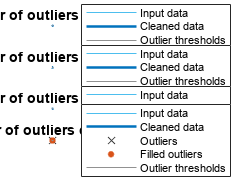

        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Cleaned data")

    % Plot outliers
    plot(refrigeratorMicrowave_2.timeCurrent(outlierIndices(:,k30)),refrigeratorMicrowave_2.(k30)(outlierIndices(:,k30)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(refrigeratorMicrowave_2.timeCurrent(outlierIndices(:,k30)),cleanedRefrigeratorMicrowave_2.(k30)(outlierIndices(:,k30)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([refrigeratorMicrowave_2.timeCurrent(:); missing; refrigeratorMicrowave_2.timeCurrent(:)],...
        [thresholdHigh10.(k30)(:); missing; thresholdLow10.(k30)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k30)))
    legend("Location","EastOutside")
    ylabel(refrigeratorMicrowave_2.Properties.VariableNames{k30},"Interpreter","none")
    if k30 == N30
        xlabel("timeCurrent")
    end
end
f30.NextPlot = "new";
clear thresholdLow10 thresholdHigh10 f30 N30 k30


% Fill outliers
[cleanedRefrigeratorMicrowave_3,outlierIndices,thresholdLow8,thresholdHigh8] = ...
    filloutliers(refrigeratorMicrowave_3,"previous","movmedian",minutes(1));

% Display results
f27 = figure("Units","Normalized");
N27 = 4;
f27.Position = [0 0 1 N27/3];
tiledlayout(N27,1,"Padding","compact");
for k27 = 1:N27
    nexttile
    plot(refrigeratorMicrowave_3.timeCurrent,refrigeratorMicrowave_3.(k27),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(refrigeratorMicrowave_3.timeCurrent,cleanedRefrigeratorMicrowave_3.(k27),...

        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Cleaned data")

    % Plot outliers
    plot(refrigeratorMicrowave_3.timeCurrent(outlierIndices(:,k27)),refrigeratorMicrowave_3.(k27)(outlierIndices(:,k27)),...
        "x","Color",[64 64 64]/255,"DisplayName","Outliers")

    % Plot filled outliers
    plot(refrigeratorMicrowave_3.timeCurrent(outlierIndices(:,k27)),cleanedRefrigeratorMicrowave_3.(k27)(outlierIndices(:,k27)),".",...
        "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

    % Plot outlier thresholds
    plot([refrigeratorMicrowave_3.timeCurrent(:); missing; refrigeratorMicrowave_3.timeCurrent(:)],...
        [thresholdHigh8.(k27)(:); missing; thresholdLow8.(k27)(:)],...
        "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

    title("Number of outliers cleaned: " + nnz(outlierIndices(:,k27)))
    legend("Location","EastOutside")
    ylabel(refrigeratorMicrowave_3.Properties.VariableNames{k27},"Interpreter","none")
    if k27 == N27
        xlabel("timeCurrent")
    end
end
f27.NextPlot = "new";
clear thresholdLow8 thresholdHigh8 f27 N27 k27

## Suavizado de datos

En esta etapa, se aplicó el método de media móvil para realizar el suavizado de los datos de los refrigeradores y microondas. El objetivo principal fue reducir las variaciones bruscas y el ruido presente en las series temporales, con el fin de obtener una representación más clara del comportamiento general de cada electrodoméstico en un lapso de tiempo determinado.

Para llevar a cabo el suavizado, se utilizó una ventana de tiempo de 5 minutos para los refrigeradores y 1 minuto para los hornos de microondas. Esto implica que se calculó la media de los valores dentro de la ventana correspondiente a cada punto en el tiempo.

La elección de estas ventanas de tiempo específicas se basó en la consideración de capturar adecuadamente el trabajo de cada electrodoméstico en el lapso correspondiente. Los refrigeradores, al tener un consumo energético más estable y cambios menos rápidos, requirieron una ventana más amplia para suavizar las fluctuaciones y obtener una estimación más precisa del consumo promedio en ese período de 5 minutos. Por otro lado, los microondas, al presentar cambios más rápidos en su consumo energético, se beneficiaron de una ventana de 1 minuto para capturar con mayor fidelidad estos cambios bruscos en su funcionamiento.

El suavizado de datos mediante el método de media móvil y la aplicación de ventanas de tiempo adecuadas permitió obtener series temporales más suaves y representativas del comportamiento general de los electrodomésticos en los respectivos intervalos de tiempo considerados. Estos datos suavizados resultarán útiles para el análisis posterior y la identificación de patrones o tendencias en el consumo energético de los refrigeradores y microondas.

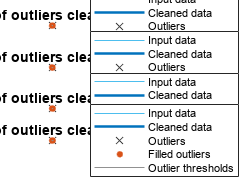

% Smooth input data
smoothCleanedRefrigeretor_1 = smoothdata(cleanedRefrigerator_1,"movmean",minutes(1));

% Display results
f7 = figure("Units","Normalized");
N7 = 4;
f7.Position = [0 0 1 N7/3];
tiledlayout(N7,1,"Padding","compact");
for k7 = 1:N7
    nexttile
    plot(cleanedRefrigerator_1.timeCurrent,cleanedRefrigerator_1.(k7),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedRefrigerator_1.timeCurrent,smoothCleanedRefrigeretor_1.(k7),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedRefrigerator_1.Properties.VariableNames{k7},"Interpreter","none")

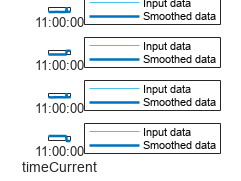

    if k7 == N7
        xlabel("timeCurrent")
    end
end
f7.NextPlot = "new";
clear f7 N7 k7


% Smooth input data
smoothCleanedRefrigeretor_2 = smoothdata(cleanedRefrigerator_2,"movmean",minutes(1));

% Display results
f8 = figure("Units","Normalized");
N8 = 4;
f8.Position = [0 0 1 N8/3];
tiledlayout(N8,1,"Padding","compact");
for k8 = 1:N8
    nexttile
    plot(cleanedRefrigerator_2.timeCurrent,cleanedRefrigerator_2.(k8),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedRefrigerator_2.timeCurrent,smoothCleanedRefrigeretor_2.(k8),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedRefrigerator_2.Properties.VariableNames{k8},"Interpreter","none")
    if k8 == N8
        xlabel("timeCurrent")
    end
end

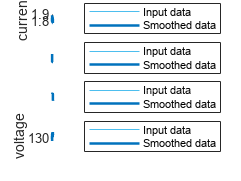

f8.NextPlot = "new";
clear f8 N8 k8


% Smooth input data
smoothCleanedRefrigeretor_3 = smoothdata(cleanedRefrigerator_3,"movmean",minutes(1));

% Display results
f9 = figure("Units","Normalized");
N9 = 4;
f9.Position = [0 0 1 N9/3];
tiledlayout(N9,1,"Padding","compact");
for k9 = 1:N9
    nexttile
    plot(cleanedRefrigerator_3.timeCurrent,cleanedRefrigerator_3.(k9),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedRefrigerator_3.timeCurrent,smoothCleanedRefrigeretor_3.(k9),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedRefrigerator_3.Properties.VariableNames{k9},"Interpreter","none")
    if k9 == N9
        xlabel("timeCurrent")
    end
end

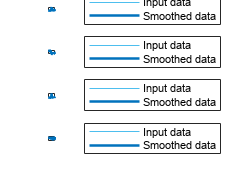

f9.NextPlot = "new";
clear f9 N9 k9


% Smooth input data
smoothCleanedRefrigeretor_4 = smoothdata(cleanedRefrigerator_4,"movmean",minutes(1));

% Display results
f10 = figure("Units","Normalized");
N10 = 4;
f10.Position = [0 0 1 N10/3];
tiledlayout(N10,1,"Padding","compact");
for k10 = 1:N10
    nexttile
    plot(cleanedRefrigerator_4.timeCurrent,cleanedRefrigerator_4.(k10),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedRefrigerator_4.timeCurrent,smoothCleanedRefrigeretor_4.(k10),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedRefrigerator_4.Properties.VariableNames{k10},"Interpreter","none")
    if k10 == N10
        xlabel("timeCurrent")
    end
end
f10.NextPlot = "new";

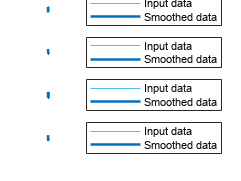

clear f10 N10 k10


% Smooth input data
smoothCleanedMicrowave_1 = smoothdata(cleanedMicrowave_1,"movmean",minutes(1));

% Display results
f11 = figure("Units","Normalized");
N11 = 4;
f11.Position = [0 0 1 N11/3];
tiledlayout(N11,1,"Padding","compact");
for k11 = 1:N11
    nexttile
    plot(cleanedMicrowave_1.timeCurrent,cleanedMicrowave_1.(k11),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedMicrowave_1.timeCurrent,smoothCleanedMicrowave_1.(k11),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedMicrowave_1.Properties.VariableNames{k11},"Interpreter","none")
    if k11 == N11
        xlabel("timeCurrent")
    end
end
f11.NextPlot = "new";
clear f11 N11 k11

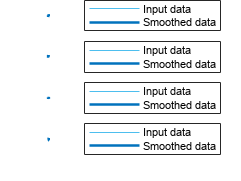



% Smooth input data
smoothCleanedMicrowave_2 = smoothdata(cleanedMicrowave_2,"movmean",minutes(1));

% Display results
f12 = figure("Units","Normalized");
N12 = 4;
f12.Position = [0 0 1 N12/3];
tiledlayout(N12,1,"Padding","compact");
for k12 = 1:N12
    nexttile
    plot(cleanedMicrowave_2.timeCurrent,cleanedMicrowave_2.(k12),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedMicrowave_2.timeCurrent,smoothCleanedMicrowave_2.(k12),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedMicrowave_2.Properties.VariableNames{k12},"Interpreter","none")
    if k12 == N12
        xlabel("timeCurrent")
    end
end

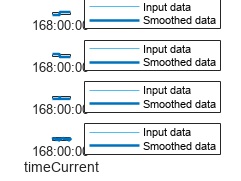

f12.NextPlot = "new";
clear f12 N12 k12


% Smooth input data
smoothCleanedMicrowave_3 = smoothdata(cleanedMicrowave_3,"movmean",minutes(1));

% Display results
f13 = figure("Units","Normalized");
N13 = 4;
f13.Position = [0 0 1 N13/3];
tiledlayout(N13,1,"Padding","compact");
for k13 = 1:N13
    nexttile
    plot(cleanedMicrowave_3.timeCurrent,cleanedMicrowave_3.(k13),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedMicrowave_3.timeCurrent,smoothCleanedMicrowave_3.(k13),"Color",[0 114 189]/255,...
        "LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedMicrowave_3.Properties.VariableNames{k13},"Interpreter","none")
    if k13 == N13
        xlabel("timeCurrent")
    end
end

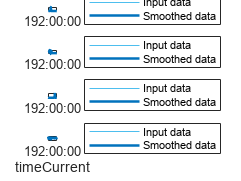

f13.NextPlot = "new";
clear f13 N13 k13


% Smooth input data
smoothCleanedRefrigeratorMicrowave_1 = smoothdata(cleanedRefrigeratorMicrowave_1,"movmean",minutes(1));

% Display results
f22 = figure("Units","Normalized");
N22 = 4;
f22.Position = [0 0 1 N22/3];
tiledlayout(N22,1,"Padding","compact");
for k22 = 1:N22
    nexttile
    plot(cleanedRefrigeratorMicrowave_1.timeCurrent,cleanedRefrigeratorMicrowave_1.(k22),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedRefrigeratorMicrowave_1.timeCurrent,smoothCleanedRefrigeratorMicrowave_1.(k22),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedRefrigeratorMicrowave_1.Properties.VariableNames{k22},"Interpreter","none")
    if k22 == N22
        xlabel("timeCurrent")
    end
end

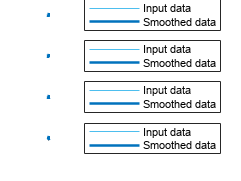

f22.NextPlot = "new";
clear f22 N22 k22


% Smooth input data
smoothCleanedRefrigeratorMicrowave_2 = smoothdata(cleanedRefrigeratorMicrowave_2,"movmean",minutes(1));

% Display results
f5 = figure("Units","Normalized");
N5 = 4;
f5.Position = [0 0 1 N5/3];
tiledlayout(N5,1,"Padding","compact");
for k5 = 1:N5
    nexttile
    plot(cleanedRefrigeratorMicrowave_2.timeCurrent,cleanedRefrigeratorMicrowave_2.(k5),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedRefrigeratorMicrowave_2.timeCurrent,smoothCleanedRefrigeratorMicrowave_2.(k5),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedRefrigeratorMicrowave_2.Properties.VariableNames{k5},"Interpreter","none")
    if k5 == N5
        xlabel("timeCurrent")
    end
end

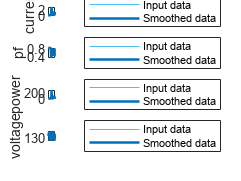

f5.NextPlot = "new";
clear f5 N5 k5



% Smooth input data
smoothCleanedRefrigeratorMicrowave_3 = smoothdata(cleanedRefrigeratorMicrowave_3,"movmean",minutes(1));

% Display results
f23 = figure("Units","Normalized");
N23 = 4;
f23.Position = [0 0 1 N23/3];
tiledlayout(N23,1,"Padding","compact");
for k23 = 1:N23
    nexttile
    plot(cleanedRefrigeratorMicrowave_3.timeCurrent,cleanedRefrigeratorMicrowave_3.(k23),...
        "Color",[77 190 238]/255,"DisplayName","Input data")
    hold on
    plot(cleanedRefrigeratorMicrowave_3.timeCurrent,smoothCleanedRefrigeratorMicrowave_3.(k23),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Smoothed data")
    legend("Location","EastOutside")
    ylabel(cleanedRefrigeratorMicrowave_3.Properties.VariableNames{k23},"Interpreter","none")
    if k23 == N23
        xlabel("timeCurrent")
    end
end
f23.NextPlot = "new";
clear f23 N23 k23

## Normalización Datos

En esta etapa, se procedió a normalizar los parámetros de corriente, potencia y voltaje utilizando el método Z-score con la desviación estándar. Es importante destacar que el factor de potencia, al ser una medida adimensional que ya se encuentra limitada a un rango de 0 a 1, no fue necesario normalizarlo mediante el método Z-score, ya que sus valores se encuentran dentro de un rango específico y no presentan la misma variabilidad que los demás parámetros.

El método Z-score es una técnica comúnmente utilizada para estandarizar variables y reducir la influencia de la escala en el análisis de datos. Consiste en calcular la desviación estándar y la media de cada parámetro y luego transformar los valores originales en desviaciones estándar con respecto a la media.

Para llevar a cabo la normalización, se realizó lo siguiente:

1. Se calculó la media y la desviación estándar de los conjuntos de datos de corriente, potencia y voltaje.

2. Se aplicó la fórmula del Z-score a cada valor de corriente, potencia y voltaje, utilizando la siguiente ecuación: 

   Z = (valor - media) / desviación estándar

Donde Z representa el valor transformado en desviaciones estándar, el valor es el dato original, la media es la media del conjunto de datos y la desviación estándar es la desviación estándar del conjunto de datos.

Al aplicar esta normalización, se logró que los valores de corriente, potencia y voltaje estén expresados en términos de su relación con la media y la variabilidad de cada parámetro. Esto facilitará el análisis comparativo y la detección de patrones o anomalías en los datos normalizados.

La normalización de los datos mediante el método Z-score contribuye a homogeneizar las escalas de los parámetros analizados, lo cual facilita su interpretación y comparación en el análisis posterior.

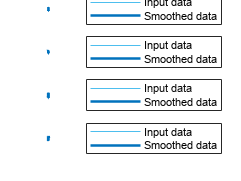

% Normalize Data
normRefrigerator_1 = normalize(smoothCleanedRefrigeretor_1,...
    "DataVariables",["current","power","voltage"]);

% Display results
f15 = figure("Units","Normalized");
dv = [1 3 4];
N15 = numel(dv);
f15.Position = [0 0 1 N15/3];
tiledlayout(N15,1,"Padding","compact");
for k15 = 1:N15
    nexttile
    plot(smoothCleanedRefrigeretor_1.timeCurrent,normRefrigerator_1.(dv(k15)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedRefrigeretor_1.Properties.VariableNames{dv(k15)},"Interpreter","none")
    if k15 == N15
        xlabel("timeCurrent")
    end
end
f15.NextPlot = "new";
clear f15 dv N15 k15


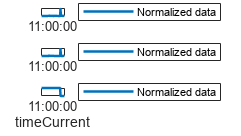


% Normalize Data
normRefrigerator_2 = normalize(smoothCleanedRefrigeretor_2,...
    "DataVariables",["current","power","voltage"]);

% Display results
f19 = figure("Units","Normalized");
dv2 = [1 3 4];
N19 = numel(dv2);
f19.Position = [0 0 1 N19/3];
tiledlayout(N19,1,"Padding","compact");
for k19 = 1:N19
    nexttile
    plot(smoothCleanedRefrigeretor_2.timeCurrent,normRefrigerator_2.(dv2(k19)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedRefrigeretor_2.Properties.VariableNames{dv2(k19)},"Interpreter","none")
    if k19 == N19
        xlabel("timeCurrent")
    end
end
f19.NextPlot = "new";
clear f19 dv2 N19 k19


% Normalize Data
normRefrigerator_3 = normalize(smoothCleanedRefrigeretor_3,...
    "DataVariables",["current","power","voltage"]);

% Display results
f18 = figure("Units","Normalized");
dv3 = [1 3 4];
N18 = numel(dv3);

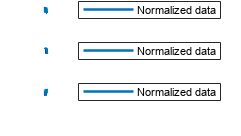

f18.Position = [0 0 1 N18/3];
tiledlayout(N18,1,"Padding","compact");
for k18 = 1:N18
    nexttile
    plot(smoothCleanedRefrigeretor_3.timeCurrent,normRefrigerator_3.(dv3(k18)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedRefrigeretor_3.Properties.VariableNames{dv3(k18)},"Interpreter","none")
    if k18 == N18
        xlabel("timeCurrent")
    end
end
f18.NextPlot = "new";
clear f18 dv3 N18 k18


% Normalize Data
normRefrigerator_4 = normalize(smoothCleanedRefrigeretor_4,...
    "DataVariables",["current","power","voltage"]);

% Display results
f17 = figure("Units","Normalized");
dv4 = [1 3 4];
N17 = numel(dv4);
f17.Position = [0 0 1 N17/3];
tiledlayout(N17,1,"Padding","compact");

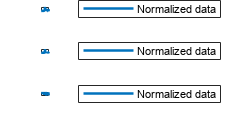

for k17 = 1:N17
    nexttile
    plot(smoothCleanedRefrigeretor_4.timeCurrent,normRefrigerator_4.(dv4(k17)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedRefrigeretor_4.Properties.VariableNames{dv4(k17)},"Interpreter","none")
    if k17 == N17
        xlabel("timeCurrent")
    end
end
f17.NextPlot = "new";
clear f17 dv4 N17 k17


% Normalize Data
normMicrowave_1 = normalize(smoothCleanedMicrowave_1,...
    "DataVariables",["current","power","voltage"]);

% Display results
f16 = figure("Units","Normalized");
dv5 = [1 3 4];
N16 = numel(dv5);

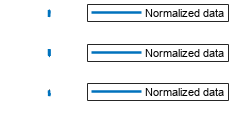

f16.Position = [0 0 1 N16/3];
tiledlayout(N16,1,"Padding","compact");
for k16 = 1:N16
    nexttile
    plot(smoothCleanedMicrowave_1.timeCurrent,normMicrowave_1.(dv5(k16)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedMicrowave_1.Properties.VariableNames{dv5(k16)},"Interpreter","none")
    if k16 == N16
        xlabel("timeCurrent")
    end
end
f16.NextPlot = "new";
clear f16 dv5 N16 k16


% Normalize Data
normMicrowave_2 = normalize(smoothCleanedMicrowave_2,...
    "DataVariables",["current","power","voltage"]);

% Display results
f20 = figure("Units","Normalized");
dv6 = [1 3 4];
N20 = numel(dv6);
f20.Position = [0 0 1 N20/3];
tiledlayout(N20,1,"Padding","compact");

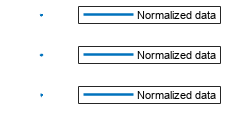

for k20 = 1:N20
    nexttile
    plot(smoothCleanedMicrowave_2.timeCurrent,normMicrowave_2.(dv6(k20)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedMicrowave_2.Properties.VariableNames{dv6(k20)},"Interpreter","none")
    if k20 == N20
        xlabel("timeCurrent")
    end
end
f20.NextPlot = "new";
clear f20 dv6 N20 k20


% Normalize Data
normMicrowave_3 = normalize(smoothCleanedMicrowave_3,...
    "DataVariables",["current","power","voltage"]);

% Display results
f21 = figure("Units","Normalized");
dv7 = [1 3 4];
N21 = numel(dv7);

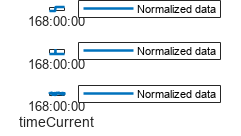

f21.Position = [0 0 1 N21/3];
tiledlayout(N21,1,"Padding","compact");
for k21 = 1:N21
    nexttile
    plot(smoothCleanedMicrowave_3.timeCurrent,normMicrowave_3.(dv7(k21)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedMicrowave_3.Properties.VariableNames{dv7(k21)},"Interpreter","none")
    if k21 == N21
        xlabel("timeCurrent")
    end
end
f21.NextPlot = "new";
clear f21 dv7 N21 k21


% Normalize Data
normRefrigeratorMicrowave_1 = normalize(smoothCleanedRefrigeratorMicrowave_1,...
    "DataVariables",["current","power","voltage"]);

% Display results
f25 = figure("Units","Normalized");
dv9 = [1 3 4];
N25 = numel(dv9);

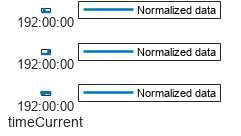

f25.Position = [0 0 1 N25/3];
tiledlayout(N25,1,"Padding","compact");
for k25 = 1:N25
    nexttile
    plot(smoothCleanedRefrigeratorMicrowave_1.timeCurrent,normRefrigeratorMicrowave_1.(dv9(k25)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedRefrigeratorMicrowave_1.Properties.VariableNames{dv9(k25)},"Interpreter","none")
    if k25 == N25
        xlabel("timeCurrent")
    end
end
f25.NextPlot = "new";
clear f25 dv9 N25 k25


% Normalize Data
normRefrigeratorMicrowave_2 = normalize(smoothCleanedRefrigeratorMicrowave_2,...
    "DataVariables",["current","power","voltage"]);

% Display results
f24 = figure("Units","Normalized");
dv8 = [1 3 4];
N24 = numel(dv8);
f24.Position = [0 0 1 N24/3];
tiledlayout(N24,1,"Padding","compact");

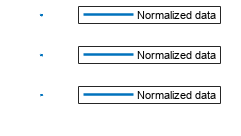

for k24 = 1:N24
    nexttile
    plot(smoothCleanedRefrigeratorMicrowave_2.timeCurrent,normRefrigeratorMicrowave_2.(dv8(k24)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedRefrigeratorMicrowave_2.Properties.VariableNames{dv8(k24)},"Interpreter","none")
    if k24 == N24
        xlabel("timeCurrent")
    end
end
f24.NextPlot = "new";
clear f24 dv8 N24 k24


% Normalize Data
normRefrigeratorMicrowave_3 = normalize(smoothCleanedRefrigeratorMicrowave_3,...
    "DataVariables",["current","power","voltage"]);

% Display results
f26 = figure("Units","Normalized");
dv10 = [1 3 4];
N26 = numel(dv10);

f26.Position = [0 0 1 N26/3];
tiledlayout(N26,1,"Padding","compact");
for k26 = 1:N26
    nexttile
    plot(smoothCleanedRefrigeratorMicrowave_3.timeCurrent,normRefrigeratorMicrowave_3.(dv10(k26)),...
        "Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","Normalized data")
    legend("Location","EastOutside")
    ylabel(smoothCleanedRefrigeratorMicrowave_3.Properties.VariableNames{dv10(k26)},"Interpreter","none")
    if k26 == N26
        xlabel("timeCurrent")
    end
end
f26.NextPlot = "new";
clear f26 dv10 N26 k26

## Guardando Variables

% save('DatosLimpios_junio')

## Crando modelos clásicos

### Creando data sets

El refri 1 tiene solo 78088 por lo que lo dejaremos fuera y tomaremos 1,000,000 de datos de las demas tablas

También agrgaremos una variable que sirva de etiqueta.

normRefrigerator_2.appliances = ones(size(normRefrigerator_2.current));
normRefrigerator_3.appliances = ones(size(normRefrigerator_3.current));
normRefrigerator_4.appliances = ones(size(normRefrigerator_4.current));
normMicrowave_1.appliances = ones(size(normMicrowave_1.current))*2;
normMicrowave_2.appliances = ones(size(normMicrowave_2.current))*2;
normMicrowave_3.appliances = ones(size(normMicrowave_3.current))*2;
normRefrigeratorMicrowave_1.appliances = ones(size(normRefrigeratorMicrowave_1.current))*3;
normRefrigeratorMicrowave_2.appliances = ones(size(normRefrigeratorMicrowave_2.current))*3;
normRefrigeratorMicrowave_3.appliances = ones(size(normRefrigeratorMicrowave_3.current))*3;

Formamos DataSet

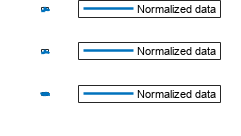

n_samples1 = 100000;
dataSet1 =  timetable2table([ ...

           datasample(normRefrigerator_2,n_samples1,'Replace',false);
           datasample(normRefrigerator_3,n_samples1,'Replace',false);
           datasample(normRefrigerator_4,n_samples1,'Replace',false);
           datasample(normMicrowave_1,n_samples1,'Replace',false);
           datasample(normMicrowave_2,n_samples1,'Replace',false);
           datasample(normMicrowave_3,n_samples1,'Replace',false); ...
           datasample(normRefrigeratorMicrowave_1,n_samples1,'Replace',false);
           datasample(normRefrigeratorMicrowave_2,n_samples1,'Replace',false);
           datasample(normRefrigeratorMicrowave_3,n_samples1,'Replace',false);]);

n_samples2 = 1000000;
dataSet2 =  timetable2table([ ...
           datasample(normRefrigerator_2,n_samples2,'Replace',false);
           datasample(normRefrigerator_3,n_samples2,'Replace',false);
           datasample(normRefrigerator_4,n_samples2,'Replace',false);
           datasample(normMicrowave_1,n_samples2,'Replace',false);
           datasample(normMicrowave_2,n_samples2,'Replace',false);
           datasample(normMicrowave_3,n_samples2,'Replace',false); ...
           datasample(normRefrigeratorMicrowave_1,n_samples2,'Replace',false);
           datasample(normRefrigeratorMicrowave_2,n_samples2,'Replace',false);
           datasample(normRefrigeratorMicrowave_3,n_samples2,'Replace',false);]);

Datos de entrenamiento

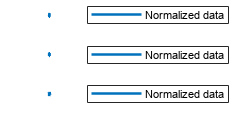

dataPartitions1 = cvpartition(dataSet1.appliances,"HoldOut",0.4);

trainDataSet1 =  dataSet1(training(dataPartitions1),2:end);    
testDataSet1 =  dataSet1(test(dataPartitions1),2:end);

dataPartitions2 = cvpartition(dataSet2.appliances,"HoldOut",0.4);
trainDataSet2 =  dataSet2(training(dataPartitions2),2:end);
testDataSet2 =  dataSet2(test(dataPartitions2),2:end);

